# **demo12 of Im2mesh package**

demo12 - Use polyshape to define geometry for mesh generation

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Overview

Polyshape is a MATLAB built-in object for polygon-like shapes. Polyshape is easy to play with. We will use object functions of polyshape to create single-part or multi-part geometry. Please refer to the following webpage about object functions of polyshape: [https://www.mathworks.com/help/matlab/ref/polyshape.html](https://www.mathworks.com/help/matlab/ref/polyshape.html)

## Initialize

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Single-part geometry

### A polyshape

Let's create a polyshape (for a single-part geometry). 

Suppose we want a square with a hole.

% square
vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

% circle
t = 0.05:0.05:2*pi;
x1 = 5 + 1.5*cos(t);
y1 = 5 + 1.5*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

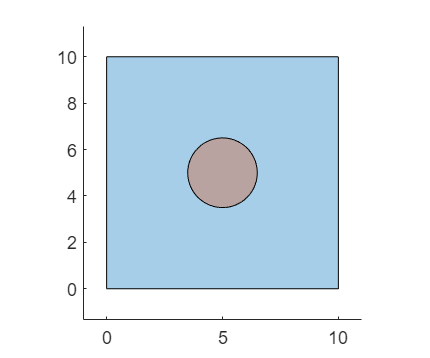

plot( [psSq; psCircle] ); 
axis equal

Perform boolean operation to create a square with a hole.

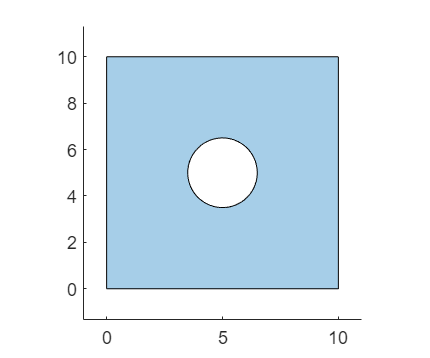

psSqHole = subtract(psSq, psCircle);

plot(psSqHole); 
axis equal

### Polygonal boundary

We use function polyshape2bound to convert a cell array of polyshape to a cell array of polygonal boundary. 

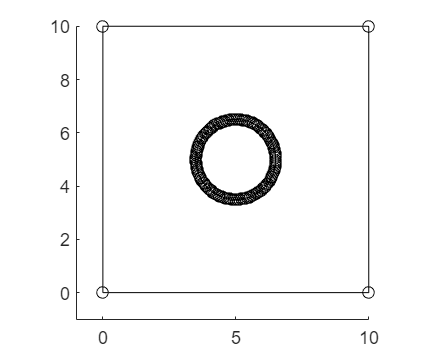

psCell = {psSqHole}; % psCell is a cell array of polyshape

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### **Simplify boundaries**

We want to reduce the number of vertices on the circle.

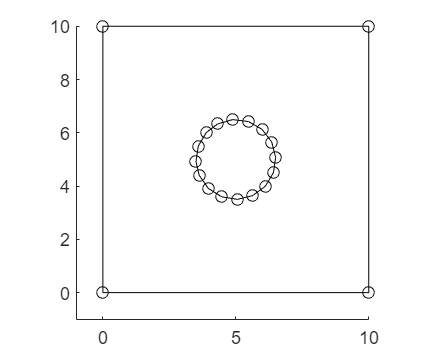

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.05;
boundsReduced = simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds( boundsReduced, false, 'ko-' );    

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh. Note that function bounds2mesh uses MESH2D (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[vert,tria,~,vert2,tria2] = bounds2mesh( boundsReduced, hmax, grad_limit, opt );

Plot mesh.

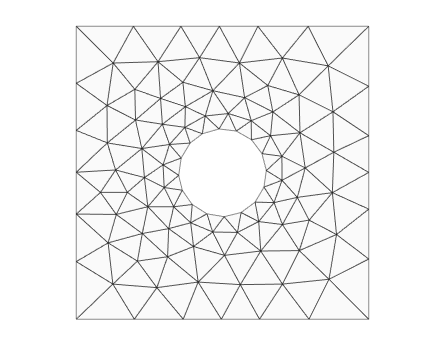

plotMeshes(vert,tria);

We can adjust hmax and grad_limit to change the mesh size.

We can use function tricost to check mesh quality. 

`    tricost( vert, tria );`

### Generate mesh via Gmsh

Gmsh can generate quasi-structured or unstructured quadrilateral mesh.

Please refer to demo11.

## Refine mesh

There are several methods to refine mesh:

- Refine mesh by splitting all elements

- Specify mesh size at a point

- Specify mesh size in an area

- Add interior constraint edges

Please refer to demo17 for how to refine mesh.

## Mesh seed

It's possible to add mesh seed to the polygonal boundary before mesh generation. Please refer to demo16 for how to add mesh seeds.

Seeds are defined as markers that you place along the edges of a region. We can use seeds to specify target mesh density in a region.

## Multi-part geometry

### Multiple polyshapes

Let's create multiple polyshapes for multi-part geometry.

clearvars

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create three rods - A B C, and combine them using function union.

psRodBase = scale( psSq, [1, 0.05]);

psRodA = rotate( psRodBase, 155 );
psRodA = translate( psRodA, [6 8] );
psRodB = translate( psRodBase, [1 9] );
psRodC = translate( psRodBase, [-1 5] );

psRodABC = union([ psRodA; psRodB; psRodC ]);

Create a circle.

t = 0.05:0.03:2*pi;
x1 = 8 + 1.5*cos(t);
y1 = 9.5 + 1.5*sin(t);
psCircle = polyshape(x1,y1);

Plot them together.

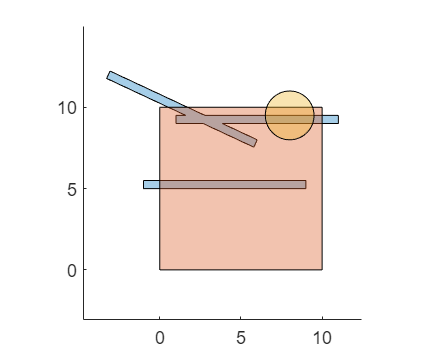

plot( [psRodABC; psSq; psCircle] ); 
axis equal

We saw that they are overlapped.

### Boolean operations

We use boolean operations to remove overlapped regions.

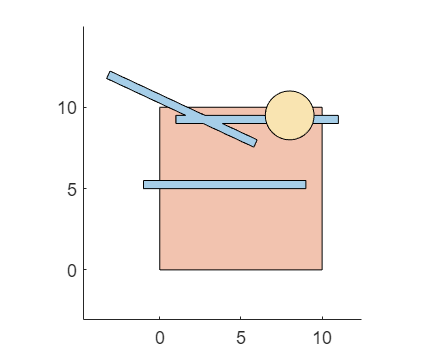

psBlock = subtract( psSq, psRodABC );
psBlock = subtract( psBlock, psCircle );

psRodABC = subtract( psRodABC, psCircle );

plot( [psRodABC; psBlock; psCircle] ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

psCell = { psRodABC; psBlock; psCircle };

% plot psCell
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

### Add intersect points (optional)

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds', and use function addIntersectPnts to add intersect points to 'bounds'. 

Note that if we don't add intersect points, mesh generation may fail.

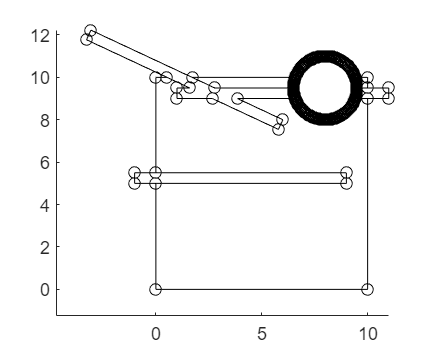

bounds = polyshape2bound(psCell);

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

We saw that there are a lot of vertices on the circle.

### Simplify boundaries

We want to reduce the number of vertices on the circle.

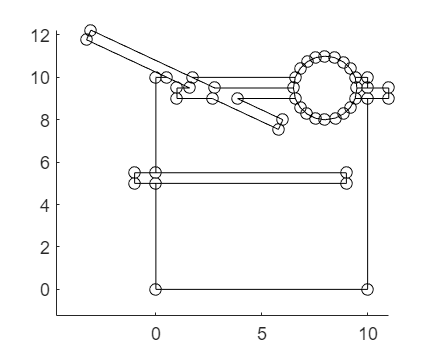

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.025;
boundsReduced = simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds(boundsReduced,false,'ko-')

Awesome! We saw that the number of vertices on the circle reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

### Generate mesh via MESH2D

To generate mesh, we use function bounds2mesh. Note that function bounds2mesh uses MESH2D (developed by Darren Engwirda) as mesh generator.

hmax = 500; 
grad_limit = 0.25;
opt = [];
opt.disp = inf;     % silence verbosity

[vert,tria,tnum,vert2,tria2] = bounds2mesh( boundsReduced, hmax, grad_limit, opt );

Plot mesh.

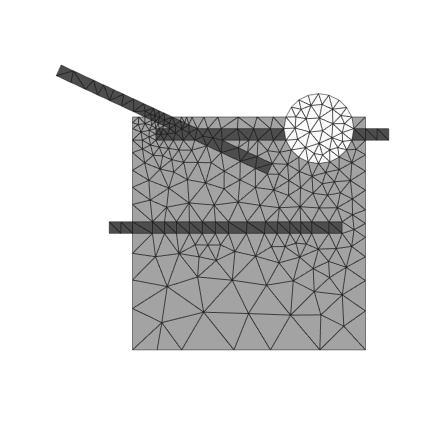

plotMeshes(vert,tria,tnum);

Awesome!

We saw that the mesh in the rod is very coarse. It's possible to refine mesh. Please refer to demo17.

We can use function tricost to check mesh quality. 

`    tricost( vert, tria );`

We can use the following command to create PDE model object (for Matlab PDE toolbox).

### Generate mesh via Gmsh

Gmsh can generate quasi-structured or unstructured quadrilateral mesh.

Please refer to demo11.

### Generate mesh via generateMesh

We can also generate mesh via Matlab built-in function generateMesh (**need Matlab PDE toolbox**). The advantage of function generateMesh is the speed. Here, we use function bounds2meshBuiltIn as interface.

We can use un-simplified boundaries as input for function bounds2meshBuiltIn.

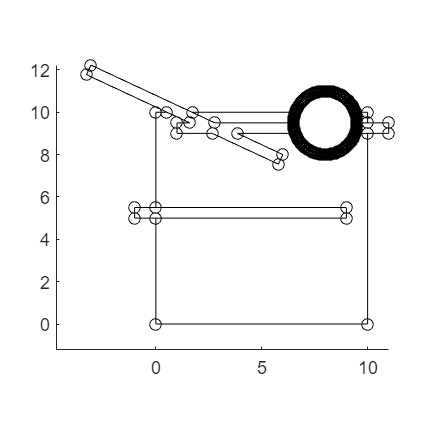

% plot boundaries
plotBounds(bounds,false,'ko-')

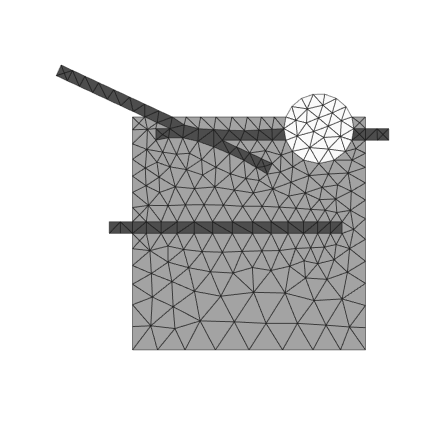

% parameters
hgrad = 1.1;
hmax = 500;
hmin = 0.5;    % you can adjust hmin and check the difference

% generate mesh
[vert,tria,tnum,vert2,tria2,model1,model2] = bounds2meshBuiltIn( bounds, hgrad, hmax, hmin );

% In the output argument, model1 and model2 are pde model objects.

plotMeshes(vert,tria,tnum);

**Comment**

When using function generateMesh in Matlab 2021b, I noticed that some edges in mesh are slightly distorted. In newer Matlab version (2024a), I didn't observe this issue. Therefore, the drawback of function generateMesh is the non-consistency between different Matlab version. That's the reason why I don't like to use function generateMesh.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo